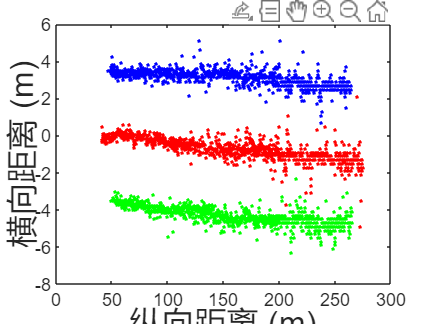

% 进行标定数据与雷达数据的映射工作，并作图
% readData;
[dirLaneFlag, meanY] = check_dir(RadarData);
b_left = meanY - 7.2;
b_right = meanY + 7.2;
if mean(Lane1(:, 7), 1) > 0    % 判断东向速度的正负，正为-1，负为1
    dirLane2EastFlage = -1;
else
    dirLane2EastFlage = 1;
end

[LaneRadarTrack1] = mapLane2Radar(RadarData, Lane1, dirLaneFlag, meanY);
[LaneRadarTrack2] = mapLane2Radar(RadarData, Lane2, dirLaneFlag, meanY);
[LaneRadarTrack3] = mapLane2Radar(RadarData, Lane3, dirLaneFlag, meanY);
LaneRadarTrack1_choose = LaneRadarTrack1(~isnan(LaneRadarTrack1(:, 1)), :);
LaneRadarTrack2_choose = LaneRadarTrack2(~isnan(LaneRadarTrack2(:, 2)), :);
LaneRadarTrack3_choose = LaneRadarTrack3(~isnan(LaneRadarTrack3(:, 3)), :);

figure("Name", "RTK Data being identified in Radar data")
plot(LaneRadarTrack1_choose(:, 2), LaneRadarTrack1_choose(:, 3),'b.')
hold on
plot(LaneRadarTrack2_choose(:, 2), LaneRadarTrack2_choose(:, 3),'r.')
plot(LaneRadarTrack3_choose(:, 2), LaneRadarTrack3_choose(:, 3),'g.')
hold off
% Create ylabel
ylabel({'横向距离 (m)'},'FontSize',18);
% Create xlabel
xlabel({'纵向距离 (m)'},'FontSize',18);

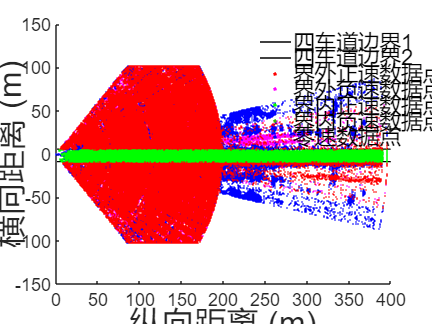

% 将雷达点云数据分为零速点，界外正速点，界外负速点，界内正速点，界内负速点，并作图

[k1, b1] = line_plofit(LaneRadarTrack1_choose((LaneRadarTrack1_choose(:, 2) > 200), 2), LaneRadarTrack1_choose((LaneRadarTrack1_choose(:, 2) > 200), 3));
[k2, b2] = line_plofit(LaneRadarTrack2_choose((LaneRadarTrack2_choose(:, 2) > 200), 2), LaneRadarTrack2_choose((LaneRadarTrack2_choose(:, 2) > 200), 3));
[k3, b3] = line_plofit(LaneRadarTrack3_choose((LaneRadarTrack3_choose(:, 2) > 200), 2), LaneRadarTrack3_choose((LaneRadarTrack3_choose(:, 2) > 200), 3));

k = (k1 + k2 + k3) / 3;
% [b_left, b_right] = get_intercept(k, b1, b3);
n_radar_data = size(RadarData, 1);
% n_radar_data = 100;

x_plot = 1 : 400;
y_plot1 = 0 * x_plot + b_left;
y_plot2 = 0 * x_plot + b_right;
figure("Name", "3D data distribution")
hold on
plot(x_plot, y_plot1, 'k','DisplayName','四车道边界1')
plot(x_plot, y_plot2, 'k','DisplayName','四车道边界2')
idx_in_or_not = zeros(n_radar_data, 1);

% 判断界内或界外
for i = 1 : n_radar_data
    if check_in_zone(k, b_left, b_right, RadarData(i, 3), RadarData(i, 4))
        idx_in_or_not(i) = 1;
    end
end
[idx_IN, ~] = find(idx_in_or_not);
[idx_NOT_IN, ~] = find(~idx_in_or_not);

% 判断非零与否
idx_V_ZERO_OR_NOT = zeros(n_radar_data, 1);
for i = 1 : n_radar_data
    if RadarData(i, 5) == 0
        idx_V_ZERO_OR_NOT(i) = 1;
    end

end
[idx_V_ZEROS, ~] = find(idx_V_ZERO_OR_NOT);
[idx_V_NOT_ZEROS, ~] = find(~idx_V_ZERO_OR_NOT);

% 判断界内的点的速度正负
idx_POS_OR_NOT = zeros(length(idx_IN), 1);
for i = 1 : length(idx_IN)
    if RadarData(idx_IN(i), 5) > 0
        idx_POS_OR_NOT(i) = 1;
    elseif RadarData(idx_IN(i), 5) < 0
         idx_POS_OR_NOT(i) = 2;
    end
end
[idx_IN_POS, ~] = find(idx_POS_OR_NOT == 1);
idx_IN_POS = idx_IN(idx_IN_POS);
[idx_IN_NEG, ~] = find(idx_POS_OR_NOT == 2);
idx_IN_NEG = idx_IN(idx_IN_NEG);

% 判断界外的点的速度正负
idx_POS_OR_NOT = zeros(length(idx_NOT_IN), 1);
for i = 1 : length(idx_NOT_IN)
    if RadarData(idx_NOT_IN(i), 5) > 0
        idx_POS_OR_NOT(i) = 1;
    elseif RadarData(idx_NOT_IN(i), 5) < 0
         idx_POS_OR_NOT(i) = 2;
    end
end
[idx_OUT_POS, ~] = find(idx_POS_OR_NOT == 1);
idx_OUT_POS = idx_NOT_IN(idx_OUT_POS);
[idx_OUT_NEG, ~] = find(idx_POS_OR_NOT == 2);
idx_OUT_NEG = idx_NOT_IN(idx_OUT_NEG);


scatter3(RadarData(idx_OUT_POS, 3), RadarData(idx_OUT_POS, 4), RadarData(idx_OUT_POS, 5), 0.01, 'r.', 'DisplayName','界外正速数据点')
scatter3(RadarData(idx_OUT_NEG, 3), RadarData(idx_OUT_NEG, 4), RadarData(idx_OUT_NEG, 5), 0.01, 'm.', 'DisplayName','界外负速数据点')
scatter3(RadarData(idx_IN_POS, 3), RadarData(idx_IN_POS, 4), RadarData(idx_IN_POS, 5), 0.01, 'g.', 'DisplayName','界内正速数据点')
scatter3(RadarData(idx_IN_NEG, 3), RadarData(idx_IN_NEG, 4), RadarData(idx_IN_NEG, 5), 0.01, '.', 'MarkerEdgeColor', [0.25, 0.7, 0.02], 'DisplayName','界内负速数据点')
scatter3(RadarData(idx_V_ZEROS, 3), RadarData(idx_V_ZEROS, 4), RadarData(idx_V_ZEROS, 5), 0.01, 'b.', 'DisplayName', '零速数据点')

% Create ylabel
ylabel({'横向距离 (m)'},'FontSize',18);
% Create xlabel
xlabel({'纵向距离 (m)'},'FontSize',18);
% Create zlabel
zlabel({'速度 (m/s)'},'FontSize',18);
legend1 = legend('show');
set(legend1,'FontSize',12);
legend("boxoff")
hold off

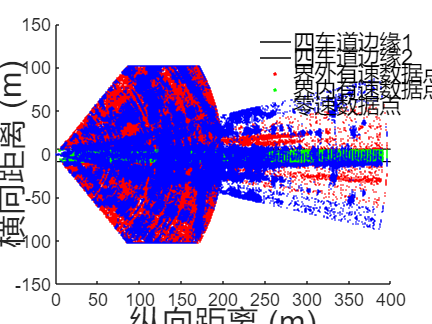


figure("Name", "2D data distribution")
hold on
plot(x_plot, y_plot1, 'k','DisplayName','四车道边缘1')
plot(x_plot, y_plot2, 'k','DisplayName','四车道边缘2')

scatter(RadarData(idx_NOT_IN, 3), RadarData(idx_NOT_IN, 4), 0.01, 'r.', 'DisplayName','界外有速数据点')
scatter(RadarData(idx_IN, 3), RadarData(idx_IN, 4), 0.01, 'g.', 'DisplayName','界内有速数据点')
scatter(RadarData(idx_V_ZEROS, 3), RadarData(idx_V_ZEROS, 4), 0.01, 'b.', 'DisplayName', '零速数据点')

% Create ylabel
ylabel({'横向距离 (m)'},'FontSize',18);
% Create xlabel
xlabel({'纵向距离 (m)'},'FontSize',18);
legend1 = legend('show');
set(legend1,'FontSize',12);
legend("boxoff")
hold off

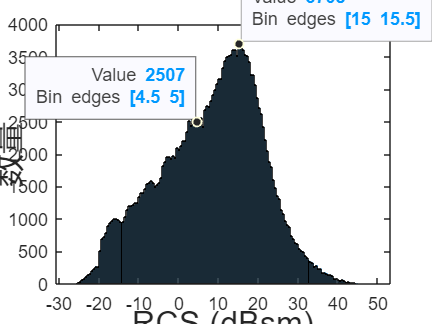


figure("Name", "RCS of data in zone")
histogram1 = histogram(RadarData(idx_IN_POS, 6));
datatip(histogram1,'DataIndex',85,'Location','northeast');
datatip(histogram1,'DataIndex',64,'Location','northwest');
% Create ylabel
ylabel({'数量'},'FontSize',18);
% Create xlabel
xlabel({'RCS (dBsm)'},'FontSize',18);

% 遍历闰秒参数，0.001作步长，17~20s
% spGap1_1 = zeros(3000, 1);
% spGap2_1 = zeros(3000, 1);
% spGap3_1 = zeros(3000, 1);
% spGap1_2 = zeros(3000, 1);
% spGap2_2 = zeros(3000, 1);
% spGap3_2 = zeros(3000, 1);
% for i = 1 : 3000
%     [LaneRadarTrack1] = mapLane2Radar(RadarData, Lane1, 17 + i / 1000, dirLaneFlag, meanY);
%     spGap1_1(i) = mean(abs(LaneRadarTrack1(:, 14))); % Track1: min_val = 0.0691771, min_idx = 856
%     spGap1_2(i) = mean(abs(LaneRadarTrack1(:, 12)));
%     [LaneRadarTrack2] = mapLane2Radar(RadarData, Lane2, 17 + i / 1000, dirLaneFlag, meanY);
%     spGap2_1(i) = mean(abs(LaneRadarTrack2(:, 14)));    % Track2: min_val = 0.0812516985584016, min_idx = 830
%     spGap2_2(i) = mean(abs(LaneRadarTrack2(:, 12)));
%     [LaneRadarTrack3] = mapLane2Radar(RadarData, Lane3, 17 + i / 1000, dirLaneFlag, meanY);
%     spGap3_1(i) = mean(abs(LaneRadarTrack3(:, 14))); % Track3: min_val = 0.0780745007045093, min_idx = 975
%     spGap3_2(i) = mean(abs(LaneRadarTrack3(:, 12)));
%     % fprintf('%d\n%', i)
% end
% [min_val1_1, min_idx1_1] = min(spGap1_1); 
% [min_val2_1, min_idx2_1] = min(spGap2_1); 
% [min_val3_1, min_idx3_1] = min(spGap3_1);
% 
% [min_val1_2, min_idx1_2] = min(spGap1_2); 
% [min_val2_2, min_idx2_2] = min(spGap2_2); 
% [min_val3_2, min_idx3_2] = min(spGap3_2); 


% 通过标定数据，确定雷达坐标系的原点的经纬度

[k1, b1] = line_plofit(LaneRadarTrack1_choose(:, 2), LaneRadarTrack1_choose(:, 3));
[k2, b2] = line_plofit(LaneRadarTrack2_choose(:, 2), LaneRadarTrack2_choose(:, 3));
[k3, b3] = line_plofit(LaneRadarTrack3_choose(:, 2), LaneRadarTrack3_choose(:, 3));

k = (k1 + k2 + k3) / 3;
tan1 = LaneRadarTrack1_choose(:, 6) ./ LaneRadarTrack1_choose(:, 7);
tan2 = LaneRadarTrack2_choose(:, 6) ./ LaneRadarTrack2_choose(:, 7);
tan3 = LaneRadarTrack3_choose(:, 6) ./ LaneRadarTrack3_choose(:, 7);
arcTan1 = atan(tan1);
arcTan2 = atan(tan2);
arcTan3 = atan(tan3);
latitudeMean = mean([LaneRadarTrack1_choose(:, 4); LaneRadarTrack2_choose(:, 4); LaneRadarTrack3_choose(:, 4)]); % 平均纬度
theta1 = mean([arcTan1; arcTan2; arcTan3]); % 经纬度与车道坐标系之间的角度偏差
theta2 = atan(k);   % 车道与雷达坐标系之间的角度偏差
delta = 0;
theta0 = theta1 - theta2 + delta;

[ori_longitude, ori_latitude] = cal_ori_lat_and_long(theta0, LaneRadarTrack1_choose, LaneRadarTrack2_choose, LaneRadarTrack3_choose, dirLaneFlag);

figure("Name", "RTK data VS predict data in coordinate")
makerSize1 = 3;
h1 = plot(LaneRadarTrack1(:, 5), LaneRadarTrack1(:, 4),'go', 'MarkerSize', makerSize1, 'LineWidth', 0.1);
hold on
plot(LaneRadarTrack2(:, 5), LaneRadarTrack2(:, 4),'go', 'MarkerSize', makerSize1, 'LineWidth', 0.1)
plot(LaneRadarTrack3(:, 5), LaneRadarTrack3(:, 4),'go', 'MarkerSize', makerSize1, 'LineWidth', 0.1)

h2 = plot(ori_longitude, ori_latitude, 'r+', 'MarkerSize', 10, 'LineWidth', 2);

[longitude1, latitude1] = getCoordinate(LaneRadarTrack1_choose(:, 2), LaneRadarTrack1_choose(:, 3), theta0, latitudeMean, ori_longitude, ori_latitude, dirLaneFlag);
[longitude2, latitude2] = getCoordinate(LaneRadarTrack2_choose(:, 2), LaneRadarTrack2_choose(:, 3), theta0, latitudeMean, ori_longitude, ori_latitude, dirLaneFlag);
[longitude3, latitude3] = getCoordinate(LaneRadarTrack3_choose(:, 2), LaneRadarTrack3_choose(:, 3), theta0, latitudeMean, ori_longitude, ori_latitude, dirLaneFlag);

h3 = plot(longitude1, latitude1,'r^', 'MarkerSize', makerSize1, 'LineWidth', 0.1);

plot(longitude2, latitude2,'r^', 'MarkerSize', makerSize1, 'LineWidth', 0.1)
plot(longitude3, latitude3,'r^', 'MarkerSize', makerSize1, 'LineWidth', 0.1)
% Create ylabel
ylabel({'纬度(°N)'},'FontSize',18);
% Create xlabel
xlabel({'经度(°E)'},'FontSize',18);

R = 6371393;
n_lane1 = length(longitude1);
n_lane2 = length(longitude2);
n_lane3 = length(longitude3);
disErr1 = zeros(n_lane1, 1);
disErr2 = zeros(n_lane2, 1);
disErr3 = zeros(n_lane3, 1);
for i = 1 : n_lane1
    disErr1(i) = distance(LaneRadarTrack1_choose(i, 4), LaneRadarTrack1_choose(i, 5), latitude1(i), longitude1(i), R);
    if disErr1(i) > 1.5
        h4 = plot(longitude1(i), latitude1(i),'k+', 'MarkerSize', 8, 'LineWidth', 1);
    end
end

CDF1 = length(find(disErr1 < 1.5)) / n_lane1;
fprintf('%d', CDF1)

9.900990e-01

for i = 1 : n_lane2
    disErr2(i) = distance(LaneRadarTrack2_choose(i, 4), LaneRadarTrack2_choose(i, 5), latitude2(i), longitude2(i), R);
    if disErr2(i) > 1.5
        plot(longitude2(i), latitude2(i),'k+', 'MarkerSize', 8, 'LineWidth', 1)
    end
end
CDF2 = length(find(disErr2 < 1.5)) / n_lane2;
fprintf('%d', CDF2)

9.742612e-01

for i = 1 : n_lane3
    disErr3(i) = distance(LaneRadarTrack3_choose(i, 4), LaneRadarTrack3_choose(i, 5), latitude3(i), longitude3(i), R);
    if disErr3(i) > 1.5
        plot(longitude3(i), latitude3(i),'k+', 'MarkerSize', 8, 'LineWidth', 1)
    end
end
CDF3 = length(find(disErr3 < 1.5)) / n_lane3;

h(1) = plot(nan, nan, 'go', 'MarkerSize', 8, 'LineWidth', 2);
h(2) = plot(nan, nan, 'r+', 'MarkerSize', 8, 'LineWidth', 2);
h(3) = plot(nan, nan, 'r^', 'MarkerSize', 8, 'LineWidth', 2);
h(4) = plot(nan, nan, 'k+', 'MarkerSize', 8, 'LineWidth', 2);
legend(h, {'真实的经纬度坐标', '雷达原点的经纬度坐标', '估计的经纬度坐标', '位置估计误差>1.5m的坐标'}, 'Box', 'off', 'Location', 'northwest', 'FontSize',13);
set(gcf, 'Position',  [100, 100, 800, 700])
ACC_TOT = (length(find(disErr1 < 1.5)) + length(find(disErr2 < 1.5)) + length(find(disErr3 < 1.5))) / (n_lane1 + n_lane2 + n_lane3);
text(113.524587096789, 23.2623770760323, "$ACC_{TOT} = " + num2str(100 * ACC_TOT, '%.2f') + "\% $", 'Interpreter', 'latex', 'FontSize',13)

fprintf('%d', CDF3)

9.942363e-01

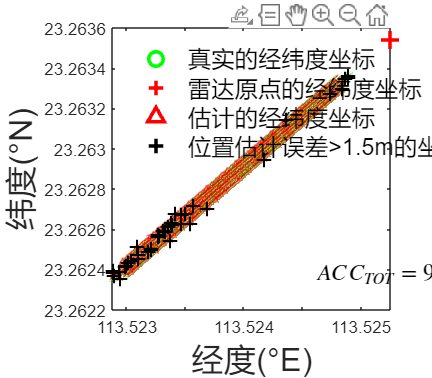

hold off

mean_disErr1 = mean(disErr1);
fprintf('%d', mean_disErr1)

5.570660e-01

mean_disErr2 = mean(disErr2);
fprintf('%d', mean_disErr2)

7.914237e-01

mean_disErr3 = mean(disErr3);
fprintf('%d', mean_disErr3)

6.190910e-01

% 计算最佳theta0，没什么卵用
% R = 6371393;
% n_lane1 = length(longitude1);
% n_lane2 = length(longitude2);
% n_lane3 = length(longitude3);
% n_test = 6000;
% CDF = zeros(n_test, 5);
% for j = 1 : 6000
%     delta = 0 + j / 1000000;
%     theta0 = theta1 - theta2 + delta;
%     [ori_longitude, ori_latitude] = cal_ori_lat_and_long(theta0, LaneRadarTrack1_choose, LaneRadarTrack2_choose, LaneRadarTrack3_choose, dirLaneFlag);
%     [longitude1, latitude1] = getCoordinate(LaneRadarTrack1(:, 2), LaneRadarTrack1(:, 3), theta0, latitudeMean, ori_longitude, ori_latitude, dirLaneFlag);
%     [longitude2, latitude2] = getCoordinate(LaneRadarTrack2(:, 2), LaneRadarTrack2(:, 3), theta0, latitudeMean, ori_longitude, ori_latitude, dirLaneFlag);
%     [longitude3, latitude3] = getCoordinate(LaneRadarTrack3(:, 2), LaneRadarTrack3(:, 3), theta0, latitudeMean, ori_longitude, ori_latitude, dirLaneFlag);
%     disErr1 = zeros(n_lane1, 1);
%     disErr2 = zeros(n_lane2, 1);
%     disErr3 = zeros(n_lane3, 1);
%     for i = 1 : n_lane1
%         disErr1(i) = distance(LaneRadarTrack1(i, 4), LaneRadarTrack1(i, 5), latitude1(i), longitude1(i), R);
%     end
%     CDF(j, 1) = length(find(disErr1 < 1.5)) / n_lane1;
%     for i = 1 : n_lane2
%         disErr2(i) = distance(LaneRadarTrack2(i, 4), LaneRadarTrack2(i, 5), latitude2(i), longitude2(i), R);
%     end
%     CDF(j, 2) = length(find(disErr2 < 1.5)) / n_lane2;
%     for i = 1 : n_lane3
%         disErr3(i) = distance(LaneRadarTrack3(i, 4), LaneRadarTrack3(i, 5), latitude3(i), longitude3(i), R);
%     end
%     CDF(j, 3) = length(find(disErr3 < 1.5)) / n_lane3;
%     if (mod(j, 100) == 0)
%         j = j;
%     end
%     CDF(j, 5) = theta0;
% end
% CDF(:, 4) = mean(CDF(:, 1:3), 2);
% [max_val, max_idx] = max(CDF(:, 4));

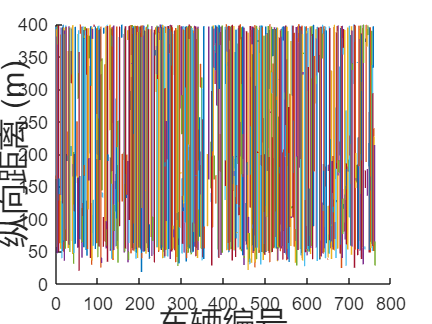

% 绘制追踪轨迹

% score_buffer = zeros(3, 30);
% for maxFailTime = 1 : 30
main
n_data= size(final_data, 1);
[carIDNum, uniqueCarID] = groupcounts(final_data(:, 2));
uniqueCarNum = length(carIDNum);
cntZeros = 0;
cntPos = 0;
figure("Name", "Algorithm efficacy")
hold on
score = 0;
for i = 1 : uniqueCarNum
    idx = find(final_data(:, 2) == uniqueCarID(i));
    if final_data(idx(1), 5) > 0
        n_tmp = length(idx);
        for j = 1 : n_tmp
            if final_data(idx(j), 5) > 0
                cntPos = cntPos + 1;
                plot(uniqueCarID(i) * ones(2, 1), [final_data(idx(1), 3); final_data(idx(end), 3)])
                % plot3(final_data(idx, 3), final_data(idx, 4), final_data(idx, 5))
                % plot3(1 : n_tmp, repmat(uniqueCarID(i), 1, n_tmp), [0; diff(final_data(idx, 3))])
                % plot3(1 : n_tmp, repmat(uniqueCarID(i), 1, n_tmp), final_data(idx, 3))
                score = score + final_data(idx(end), 3) - final_data(idx(1), 3);
                break;
            end
        end
    end
end
score = score / cntPos;
hold off

% Create ylabel
ylabel({'纵向距离 (m)'},'FontSize',18);
% Create xlabel
xlabel({'车辆编号'},'FontSize',18);


% score_buffer(1, maxFailTime) = score;
% score_buffer(2, maxFailTime) = n_data;
% score_buffer(3, maxFailTime) = uniqueCarNum;
% end

% figure(4)
% hold on
% for i = 1 : uniqueCarNum
%     idx = find(final_data(:, 2) == uniqueCarID(i));
%     if final_data(idx(1), 5) > 0
%         continue;
%     end
%     cntPos = cntPos + 1;
%     plot3(final_data(idx, 3), final_data(idx, 4), final_data(idx, 1))
%     score = score + final_data(idx(end), 3) - final_data(idx(1), 3);
% end
% hold off


% 比较C++结果与matlab结果
main
% final_data2 = readtable("D:\Competition\Pazhou_Lab\6.100.csv");
final_data2 = readtable("D:\Competition\Pazhou_Lab\Pazhou_Lab\Pazhou_Lab\result.csv");
final_data2 = final_data2.Variables;
final_data1 = final_data;
% tmp2 = final_data2(1:50000, :) - final_data1(1:50000, :);
tmp2 = final_data2 - final_data1;

% 看一下在追踪算法中追踪出来的标定数据点的经纬度误差是多少
[LaneRadarTrack1] = mapLane2Radar(RadarData, Lane1, dirLaneFlag, meanY);
[LaneRadarTrack2] = mapLane2Radar(RadarData, Lane2, dirLaneFlag, meanY);
[LaneRadarTrack3] = mapLane2Radar(RadarData, Lane3, dirLaneFlag, meanY);
LaneRadarTrack1 = LaneRadarTrack1(~isnan(LaneRadarTrack1(:, 1)), :);
LaneRadarTrack2 = LaneRadarTrack2(~isnan(LaneRadarTrack2(:, 2)), :);
LaneRadarTrack3 = LaneRadarTrack3(~isnan(LaneRadarTrack3(:, 3)), :);
% recall_buffer = zeros(1, 100);
% for maxFailTime = 1 : 100
main

Lane1DataId = [];   % 看一下LaneRadarTrack1的第cnt个点出现在final_data2的第几个点
cnt = 1;
while isempty(Lane1DataId)
    Lane1DataId = find(final_data2(:, 15) == LaneRadarTrack1(cnt, 1));
    cnt = cnt + 1;
end
carLane1Id = final_data2(Lane1DataId, 2);   % 看一下车辆一在final_data2中所属的标号

Lane2DataId = [];
cnt = 1;
while isempty(Lane2DataId)
    Lane2DataId = find(final_data2(:, 15) == LaneRadarTrack2(cnt, 1));
    cnt = cnt + 1;
end
carLane2Id = final_data2(Lane2DataId, 2);

Lane3DataId = [];
cnt = 1;
while isempty(Lane3DataId)
    Lane3DataId = find(final_data2(:, 15) == LaneRadarTrack3(cnt, 1));
    cnt = cnt + 1;
end
carLane3Id = final_data2(Lane3DataId, 2);

idxLane1 = find(final_data2(:, 2) == carLane1Id);
idxLane2 = find(final_data2(:, 2) == carLane2Id);
idxLane3 = find(final_data2(:, 2) == carLane3Id);

cnt1 = 0;
cnt2 = 0;
cnt3 = 0;

disErr1 = zeros(length(idxLane1), 1);
disErr2 = zeros(length(idxLane2), 1);
disErr3 = zeros(length(idxLane3), 1);

% 在final_data2中的车道数据，再对应回到LaneRadarTrack1中，寻找雷达编号相同的
for idx = (idxLane1)'
    radarId = final_data2(idx, 15);
    LaneDataId = find(final_data2(idx, 15) == LaneRadarTrack1(:, 1));
    if isempty(LaneDataId)
        continue;
    end
    cnt1 = cnt1 + 1;
    [disErr1(cnt1), ~] = distance(final_data2(idx, 10), final_data2(idx, 9), LaneRadarTrack1(LaneDataId, 4), LaneRadarTrack1(LaneDataId, 5), 6371393);
end

for idx = (idxLane2)'
    radarId = final_data2(idx, 15);
    LaneDataId = find(final_data2(idx, 15) == LaneRadarTrack2(:, 1));
    if isempty(LaneDataId)
        continue;
    end
    cnt2 = cnt2 + 1;
    [disErr2(cnt2), ~] = distance(final_data2(idx, 10), final_data2(idx, 9), LaneRadarTrack2(LaneDataId, 4), LaneRadarTrack2(LaneDataId, 5), 6371393);
end

for idx = (idxLane3)'
    radarId = final_data2(idx, 15);
    LaneDataId = find(final_data2(idx, 15) == LaneRadarTrack3(:, 1));
    if isempty(LaneDataId)
        continue;
    end
    cnt3 = cnt3 + 1;
    [disErr3(cnt3), ~] = distance(final_data2(idx, 10), final_data2(idx, 9), LaneRadarTrack3(LaneDataId, 4), LaneRadarTrack3(LaneDataId, 5), 6371393);
end

disErr1 = disErr1(1 : cnt1);
disErr2 = disErr2(1 : cnt2);
disErr3 = disErr3(1 : cnt3);
% recallAll = (cnt1 + cnt2 + cnt3) / (length(LaneRadarTrack1) + length(LaneRadarTrack2) + length(LaneRadarTrack3));
% recall_buffer(1, maxFailTime) = recallAll;
% end
% [bestRecall, bestMaxFailTime] = max(recall_buffer);

mean_disErr1 = mean(disErr1);
fprintf('mean_disErr1 = %d', mean_disErr1)

mean_disErr1 = 2.454002e-01

mean_disErr2 = mean(disErr2);
fprintf('mean_disErr2 = %d', mean_disErr2)

mean_disErr2 = 6.073985e-01

mean_disErr3 = mean(disErr3);
fprintf('mean_disErr3 = %d', mean_disErr3)

mean_disErr3 = 4.906204e-01


recall1 = cnt1 / length(LaneRadarTrack1);
recall2 = cnt2 / length(LaneRadarTrack2);
recall3 = cnt3 / length(LaneRadarTrack3);
fprintf('recall1 = %d', recall1)

recall1 = 1.749175e-01

fprintf('recall2 = %d', recall2)

recall2 = 5.481411e-01

fprintf('recall3 = %d', recall3)

recall3 = 5.168108e-01

recallAll = (cnt1 + cnt2 + cnt3) / (length(LaneRadarTrack1) + length(LaneRadarTrack2) + length(LaneRadarTrack3));
fprintf('recallAll = %d', recallAll)

recallAll = 4.241414e-01

% 计算每帧识别的结果数，并计算总体标准差
main
n = size(final_data, 1);
uniqueFrame = unique(final_data(:,1));
resultCntFrame = zeros(length(uniqueFrame), 1);
cnt1 = 1;
cnt2 = 1;
for i = 2 : n
    if (final_data(i, 1) ~= final_data(i-1, 1))
        resultCntFrame(cnt2) = cnt1;
        cnt2 = cnt2 + 1;
        cnt1 = 1;
    end
    cnt1 = cnt1 + 1;
end
resultCntFrame(length(uniqueFrame)) = cnt1;
fprintf('%d', std(resultCntFrame, 1))

2.144782e+00

% 追踪动态可视化
dataIdxCnt = 1;
im = cell(1, n_Gap);
filename = "Tracking dynamic visualization.gif"; % Specify the output file name
fig = figure("Name", "Tracing dynamic visualization");
set(gcf,'outerposition',get(0,'screensize'));
axis equal
hold on
ax.XLimMode = 'manual';
for cnt = 1 : n_Gap
    frameStart = frameGapIdx(cnt);  % 当前帧的在雷达数据的起始位
    nFrame = frameGapIdx(cnt + 1) - frameGapIdx(cnt);   % 该帧的帧数
    tmpIndex = zeros(nFrame, 1);
    for i = 1 : nFrame
        if check_in_zone(k, b_left, b_right, RadarData(frameStart + i - 1, 3), RadarData(frameStart + i - 1, 4))  % 在区域内
            tmpIndex(i) = 1;        % 在C++中，寻找OKIndex应该用push来代替
        end
    end
    OKIndex = find(tmpIndex) - 1;
    scatter3(RadarData(frameStart + OKIndex, 3), RadarData(frameStart + OKIndex, 4), RadarData(frameStart + OKIndex, 5), 10, 'b.')
    hold on
    while (dataIdxCnt <= size(final_data2, 1) && final_data2(dataIdxCnt, 1) == RadarData(frameStart, 1))
        x_ori = final_data2(dataIdxCnt, 3);
        y_ori = final_data2(dataIdxCnt, 4);
        carLen = final_data2(dataIdxCnt, 16);
        if final_data2(dataIdxCnt, 8) == 0
            color = 'r';
        else
            color = 'g';
        end
        plot3([x_ori - 0.5 * carLen, x_ori + 0.5 * carLen, x_ori + 0.5 * carLen, x_ori - 0.5 * carLen, x_ori - 0.5 * carLen], ...
            [y_ori - 0.9, y_ori - 0.9, y_ori + 0.9, y_ori + 0.9, y_ori - 0.9], ...
            [final_data2(dataIdxCnt, 5), final_data2(dataIdxCnt, 5), final_data2(dataIdxCnt, 5), final_data2(dataIdxCnt, 5), final_data2(dataIdxCnt, 5)],...
            color,'linewidth', 0.5)
        text(x_ori, y_ori, final_data2(dataIdxCnt, 5) + 5, num2str(final_data2(dataIdxCnt, 2)), 'FontSize', 10)

        dataIdxCnt = dataIdxCnt + 1;
    end

    xticks([0 50 100 150 200 250 300 350 400])
    yticks([-12 -7 -2 3 8])
    axis equal
    xlim([0 400])
    ylim([-11 8])
    zlim([0 40])
    title("Frame = " + num2str(cnt), 'FontSize', 16)
    % Create ylabel
    ylabel({'横向距离 (m)'},'FontSize',16, 'Position', [-4.764614121636356,-8.31722769514533,-14.391583036376083], 'Rotation', -37.5);
    % Create xlabel
    xlabel({'纵向距离 (m)'},'FontSize',16, 'Position', [211.95953143527,-25.108882797605958,-6.777221575616799], 'Rotation', 22.3);
    % Create zlabel
    zlabel({'速度 (m/s)'},'FontSize',16, 'Position', [-10.735464163759076,18.954118323903312,23.732829646529908], 'Rotation', 90);
    h1(1) = plot(nan,nan,'rs', 'MarkerSize', 8);
    h1(2) = plot(nan,nan, 'gs', 'MarkerSize', 8);
    h1(3) = plot(nan,nan, 'b.', 'MarkerSize', 8);
    legend(h1, {"小汽车", "大客车", "雷达数据"}, 'Box', 'off', 'Location', 'northwest', 'FontSize', 13, 'Position',[0.811639085894405,0.768034351145047,0.071118991331757,0.081297709923664])
    % pause(0.001)
    set(gcf,'outerposition',get(0,'screensize'));
    drawnow;
        frame = getframe(fig);
    im{cnt} = frame2im(frame);
    [A,map] = rgb2ind(im{cnt},256);
    if cnt == 1
        imwrite(A,map,filename,"gif","LoopCount",Inf,"DelayTime",0.001);
    else
        imwrite(A,map,filename,"gif","WriteMode","append","DelayTime",0.001);
    end
    hold off
end

% 输出标定参数
fprintf("theta2 = %.15f;\n", theta2)

theta2 = -0.005379312619908;


fprintf("cosTheta2 = %.15f;\n", cosTheta2)

cosTheta2 = 0.999985531532758;


fprintf("sinTheta2 = %.15f;\n", sinTheta2)

sinTheta2 = -0.005379286676413;


fprintf("theta0 = %.15f;\n", theta0)

theta0 = 0.503528786958220;


fprintf("latitudeMean = %.15f;\n", latitudeMean)

latitudeMean = 23.262842936575982;


fprintf("ori_longitude = %.15f;\n", ori_longitude)

ori_longitude = 113.525251645024227;


fprintf("ori_latitude = %.15f;\n", ori_latitude)

ori_latitude = 23.263541362638833;


fprintf("b_left = %.15f;\n", b_left)

b_left = -8.741898221657637;


fprintf("b_right = %.15f;\n", b_right)

b_right = 5.658101778342363;


fprintf("k = %.15f;\n", k)

k = -0.005379364507572;


fprintf("kAti = %.15f;\n", kAti)

kAti = 0.004217312429328;


fprintf("bAti = %.15f;\n", bAti)

bAti = 26.900626029912488;
